# Lab Session 4

## Question 1

format long e
x = (4/3 - 1).*3 - 1;
disp(x);

    -2.220446049250313e-16



x = 5.*(((1 + exp(-50)) - 1)./((1 + exp(-50)) - 1));
disp(x);

   NaN



x = log(exp(750))./100;
disp(x);

   Inf



- Catastrophic Cancellation

- Underflow

- Overflow

## Question 2

p = 1:16;
x = 10.^-p;
disp(x);

     1.000000000000000e-01     1.000000000000000e-02     1.000000000000000e-03     1.000000000000000e-04     9.999999999999999e-06     1.000000000000000e-06     1.000000000000000e-07     1.000000000000000e-08     1.000000000000000e-09     1.000000000000000e-10     1.000000000000000e-11     1.000000000000000e-12     1.000000000000000e-13     1.000000000000000e-14     1.000000000000000e-15     1.000000000000000e-16



y = (tan(x) - x)./(x.^3);
sig_digits = log10(abs(y - 1/3));
disp(sig_digits);

    -2.873299829331332e+00    -4.875043663184115e+00    -6.874849849102898e+00    -8.496812199889503e+00    -6.339513653567319e+00    -4.587227263120465e+00    -2.608872802071586e+00    -4.771212547196625e-01    -4.771212547196625e-01    -4.771212547196625e-01    -4.771212547196625e-01    -4.771212547196625e-01    -4.771212547196625e-01    -4.771212547196625e-01    -4.771212547196625e-01    -4.771212547196625e-01



figure;
semilogy(p,abs(y - 1/3));
hold on;
ymod = 1/3 + 2.*x.^2./15;
sig_digitsmod = log10(abs(y - 1/3));
disp(sig_digitsmod);

    -2.873299829331332e+00    -4.875043663184115e+00    -6.874849849102898e+00    -8.496812199889503e+00    -6.339513653567319e+00    -4.587227263120465e+00    -2.608872802071586e+00    -4.771212547196625e-01    -4.771212547196625e-01    -4.771212547196625e-01    -4.771212547196625e-01    -4.771212547196625e-01    -4.771212547196625e-01    -4.771212547196625e-01    -4.771212547196625e-01    -4.771212547196625e-01



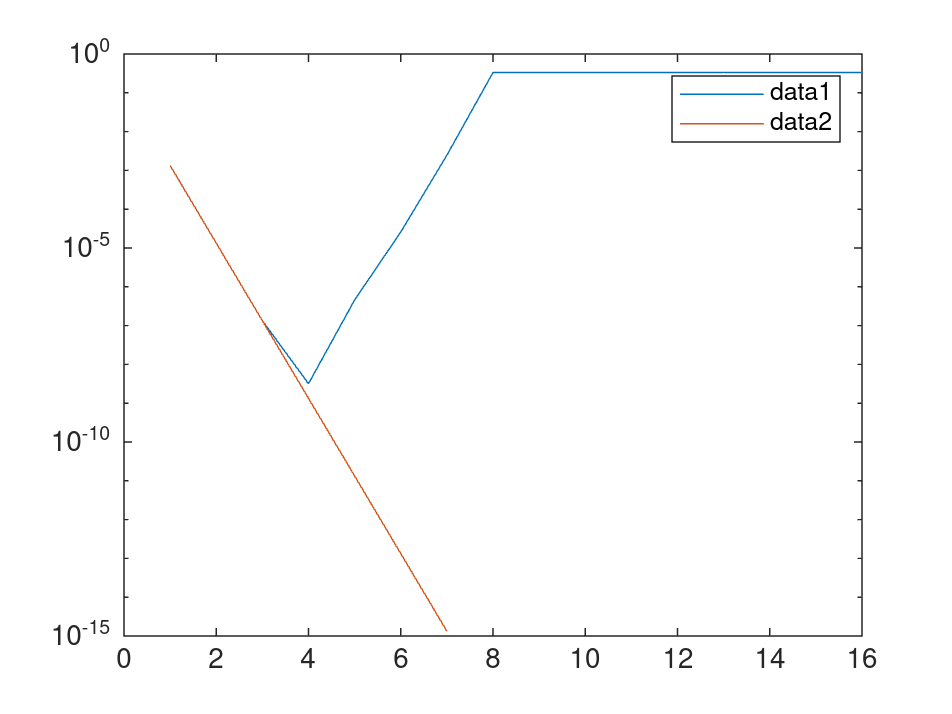

semilogy(p,abs(ymod - 1/3));
hold off;
legend('show');


p = 1:16;
x = 10.^-p;
disp(x);

     1.000000000000000e-01     1.000000000000000e-02     1.000000000000000e-03     1.000000000000000e-04     9.999999999999999e-06     1.000000000000000e-06     1.000000000000000e-07     1.000000000000000e-08     1.000000000000000e-09     1.000000000000000e-10     1.000000000000000e-11     1.000000000000000e-12     1.000000000000000e-13     1.000000000000000e-14     1.000000000000000e-15     1.000000000000000e-16



y = (exp(x) + cos(x) - sin(x) - 2)./(x.^3);
sig_digits = log10(abs(y - 1/3));
disp(sig_digits);

    -2.079179152122654e+00    -3.079181185832042e+00    -4.078228486147827e+00    -3.750402363212019e+00    -9.556332215736859e-01    -4.771212547196625e-01     5.346440877435310e+00    -4.771212547196625e-01    -4.771212547196625e-01    -4.771212547196625e-01    -4.771212547196625e-01    -4.771212547196625e-01    -4.771212547196625e-01     2.634644022547298e+01     2.934644022547298e+01    -4.771212547196625e-01



figure;
semilogy(p,abs(y - 1/3));
hold on;
ymod = 1/3 + x./24;
sig_digitsmod = log10(abs(y - 1/3));
disp(sig_digitsmod);

    -2.079179152122654e+00    -3.079181185832042e+00    -4.078228486147827e+00    -3.750402363212019e+00    -9.556332215736859e-01    -4.771212547196625e-01     5.346440877435310e+00    -4.771212547196625e-01    -4.771212547196625e-01    -4.771212547196625e-01    -4.771212547196625e-01    -4.771212547196625e-01    -4.771212547196625e-01     2.634644022547298e+01     2.934644022547298e+01    -4.771212547196625e-01



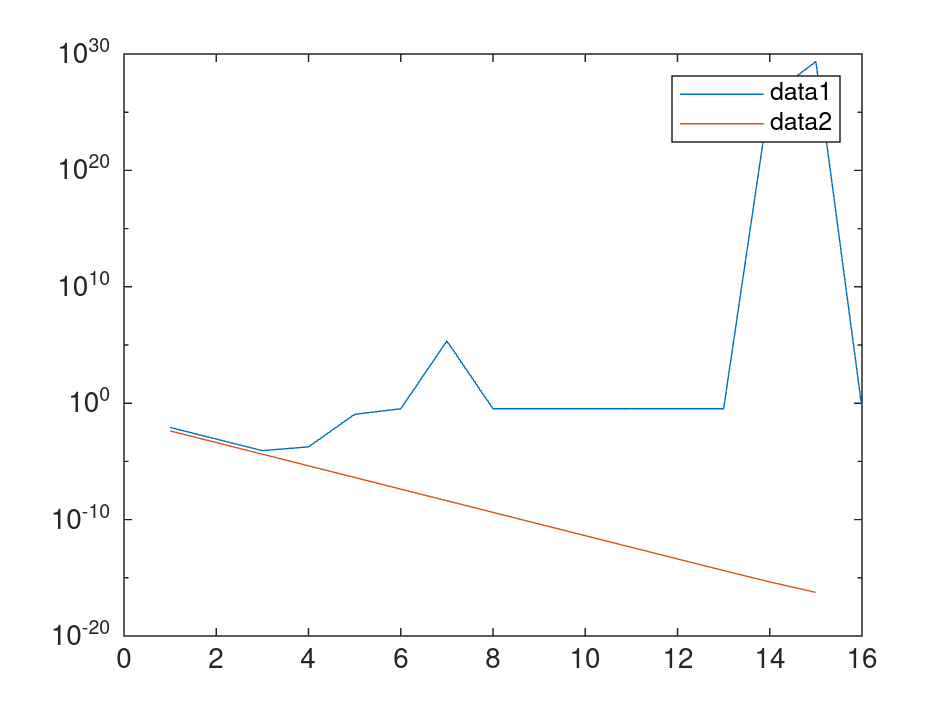

semilogy(p,abs(ymod - 1/3));
hold off;
legend('show');


p = 1:16;
x = 10.^-p;
disp(x);

     1.000000000000000e-01     1.000000000000000e-02     1.000000000000000e-03     1.000000000000000e-04     9.999999999999999e-06     1.000000000000000e-06     1.000000000000000e-07     1.000000000000000e-08     1.000000000000000e-09     1.000000000000000e-10     1.000000000000000e-11     1.000000000000000e-12     1.000000000000000e-13     1.000000000000000e-14     1.000000000000000e-15     1.000000000000000e-16



y = (exp(x) - 1)./x;
sig_digits = log10(abs(y - 1));
disp(sig_digits);

    -1.286432342826650e+00    -2.299581140482518e+00    -3.300885218735133e+00    -4.301015515302865e+00    -5.301029390700364e+00    -6.301062843767653e+00    -7.305977055789310e+00    -8.216277106889963e+00    -7.082282536105524e+00    -7.082282536105524e+00    -7.082282536105524e+00    -4.051095394185471e+00    -3.097302229124561e+00    -3.097302229124561e+00    -9.577276756913117e-01                         0



figure;
semilogy(p,abs(y - 1));
hold on;
ymod = 1 + x./2 + x.^2/6;
sig_digitsmod = log10(abs(y - 1));
disp(sig_digitsmod);

    -1.286432342826650e+00    -2.299581140482518e+00    -3.300885218735133e+00    -4.301015515302865e+00    -5.301029390700364e+00    -6.301062843767653e+00    -7.305977055789310e+00    -8.216277106889963e+00    -7.082282536105524e+00    -7.082282536105524e+00    -7.082282536105524e+00    -4.051095394185471e+00    -3.097302229124561e+00    -3.097302229124561e+00    -9.577276756913117e-01                         0



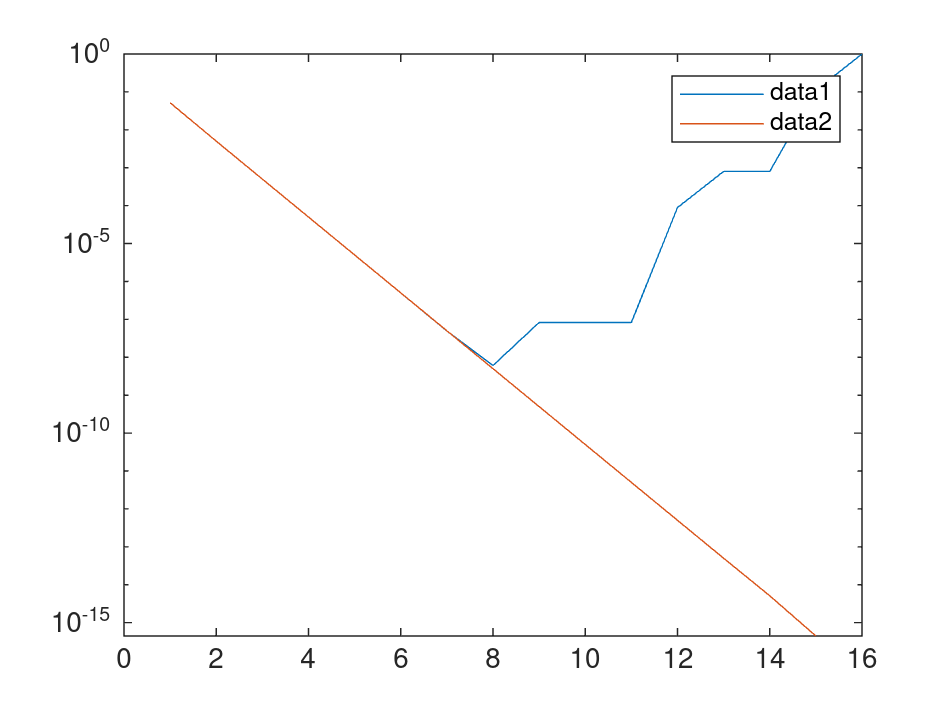

semilogy(p,abs(ymod - 1));
hold off;
legend('show');

As we can see error and number of correct significant digits improves for the rewritten expression as compared to the original expression.

## Question 3

p = [1 -18 144 -672 2016 -4032 5376 -4608 2304 -512];

a = 0.05.*rand(5, 1) + 1.95;
b = 0.05.*rand(5, 1) + 2.00;

for i = 1 : length(a)
    x = bisect(p, a(i), b(i), 1e-8);
    fprintf("Computed Root for root in [%f, %f] = ", a(i), b(i));
    disp(x);
end

Computed Root for root in [1.957881, 2.007094] = 

     1.977421972597007e+00



Computed Root for root in [1.998530, 2.021088] = 

     2.020905367040140e+00



Computed Root for root in [1.997858, 2.045787] = 

     2.002874361294552e+00



Computed Root for root in [1.974269, 2.039610] = 

     2.026746617565149e+00



Computed Root for root in [1.990014, 2.047975] = 

     2.036720363770254e+00



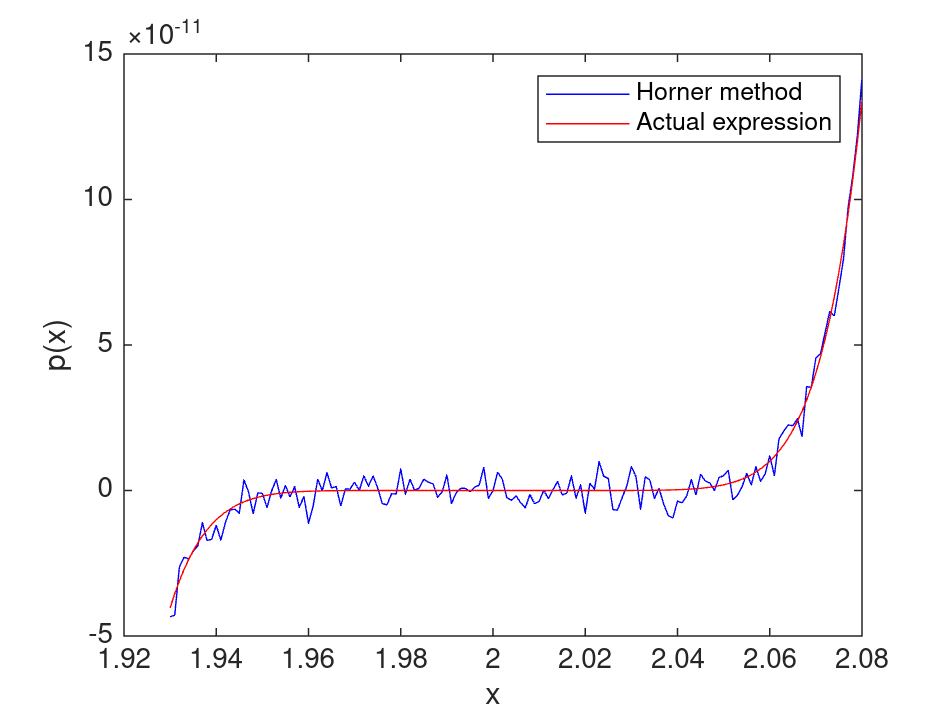



x = linspace(1.93, 2.08, 151);

p = [1 -18 144 -672 2016 -4032 5376 -4608 2304 -512];
y_horner = Horner(p, x);

y_direct = (x - 2) .^ 9;

plot(x, y_horner, "blue");
hold on;
plot(x, y_direct, "red");
hold off;

xlabel("x");
ylabel("p(x)");
legend(["Horner method", "Actual expression"]);


function y = Horner(p, x)
    n = length(p);
    y = zeros(size(x));
    
    for i = 1 : n
        y = y.*x + p(i);
    end
end

function x = bisect(p, x0, x1, tol)
    x = (x0 + x1) / 2;
    while x1 - x0 > 2*tol
        a = Horner(p, x0);
        b = Horner(p, x);       
        if a * b < 0
            x1 = x;
        else
            x0 = x;
        end
        x = (x0 + x1) / 2;
    end
end

We can observe that the Horner's method is returning a zig-zag curve crossing the x-axis at several points. So the calculated polynomial has multiple roots in the vicinity of x = 2. That is the reason why we can observe different roots getting returned for different intervals when solved by the bisection method.

This is because as polynomial is continous the actual value of it is very close to zero near x = 2. So because of rounding off errors positive values of small modulus may actually calculated as negative and vice-versa. Hence the issue of multiple roots.